clear;
angle_hops=zeros(1,15);
for i=1:15
    angle_hops(i)=(atan(1/2^(i-1)))*180/pi;
end    
tan_transform = cell(1,15);
tan_transform_inv = cell(1,15);
for i=1:15
    tan_transform{i}=[1 -1*(2^(-i+1));1*(2^(-i+1)) 1];
    tan_transform_inv{i}=[1 1*(2^(-i+1));-1*(2^(-i+1)) 1];
end    

% target_angle=55;
% transformed_vec=[1;0]
% curr_angle=0;
% for k=1:15
%     if (curr_angle<target_angle)
%        % k
%        % tan_transform{k}
%        transformed_vec=tan_transform{k}*transformed_vec;
%        curr_angle=curr_angle+angle_hops(k); 
%     else
%         % k
%         % tan_transform_inv{k}
%         transformed_vec=tan_transform_inv{k}*transformed_vec;
%        curr_angle=curr_angle-angle_hops(k);
%     end
% end
% transformed_vec=transformed_vec.*0.6073;
% sin_ans=transformed_vec(2,1)
% cos_ans=transformed_vec(1,1)

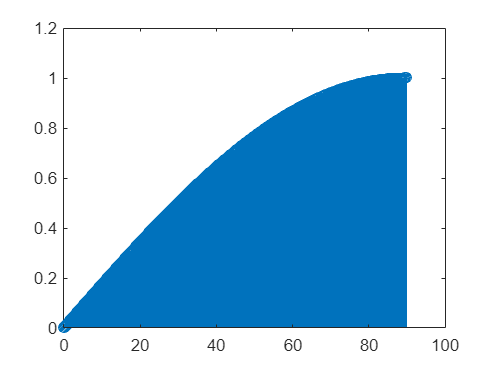


sin_ans=[];
cos_ans=[];
for target_angle=0.001:0.001:90
    transformed_vec=[1;0];
    curr_angle=0;
    for k=1:15
        if (curr_angle<target_angle)
        % k
        % tan_transform{k}
        transformed_vec=tan_transform{k}*transformed_vec;
        curr_angle=curr_angle+angle_hops(k); 
        else
        % k
        % tan_transform_inv{k}
        transformed_vec=tan_transform_inv{k}*transformed_vec;
        curr_angle=curr_angle-angle_hops(k);
        end
    end
    transformed_vec=transformed_vec.*0.6073;
    sin_ans=[sin_ans transformed_vec(2,1)];
    cos_ans=[cos_ans transformed_vec(1,1)];
end
stem(0.001:0.001:90,sin_ans);

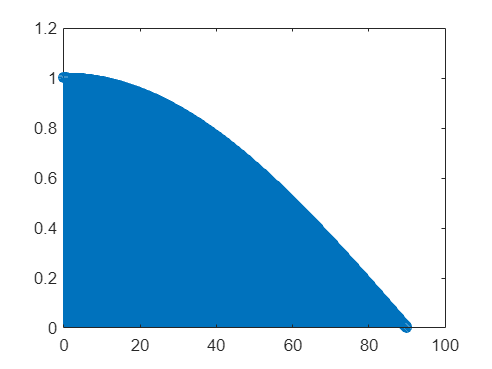

stem(0.001:0.001:90,cos_ans);